# Deploy MySQL Native Interface Database Application with MATLAB Compiler

This example shows how to write a script to analyze data stored in a MySQL® database using the MySQL native interface, and deploy the script as a standalone application. Write code that connects to a database, imports data from the database into MATLAB®, analyzes the data, and closes the database connection. Then, you can deploy the code by compiling it as a standalone application using the [Application Compiler](docid:compiler_ug#buhx63k-1) app, and then running the application on other machines.

The example uses the MySQL native interface to create the database connection. Overall, the example follows the steps described in [Create Standalone Application from MATLAB](docid:compiler_ug#bsl9c8_) and updates the steps for a standalone database application.

**Before you begin, note the following:**

- You must first install the MySQL/C++ Connector file on each machine where you plan to run the standalone application. For details about configuring the data source, see [MySQL Native Interface for Windows](docid:database_ug#mw_8d4a2b88-a308-4cc4-b1a7-cc4e69dbd4ac) or [MySQL Native Interface for macOS](docid:database_ug#mw_9a089626-ea8a-4005-90df-fabf04115e8f).

- You must have administrator privileges on each machine where you plan to run the standalone application.

## Create Function in MATLAB

Create a MATLAB script named `importMySQLNative.m` and save it in a file location of your choice. The script contains the `importMySQLNative` function, which returns the maximum product number from the data in the `productTable` database table. The function connects to a MySQL database and imports all data from `productTable`. Then, the function calculates the maximum product number. 

You must use the syntax with name-value pair arguments when you connect to the database using the [mysql](docid:database_ug#mw_f0fca8da-51fe-4f03-9986-5cde8bbed95e) function.

type importMySQLNative.m

## Create Standalone Application Using Application Compiler App

On the **MATLAB Apps** tab, on the far right of the **Apps** section, click the arrow to open the apps gallery. Under **Application Deployment**, click **Application Compiler**.

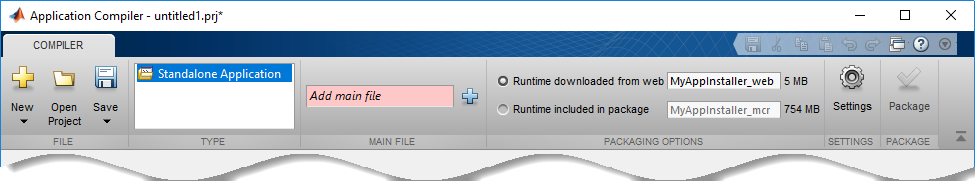

In the **MATLAB Compiler** project window, specify the main file of the MATLAB application that you want to deploy.

- In the **Main File** section of the toolstrip, click the plus sign button   to add a main file.

- In the **Add Files** dialog box, browse to the file location that contains your saved script. Select `importMySQLNative.m` and click **Open**. The Application Compiler app adds the `importMySQLNative` function to the list of main files.

Decide whether to include the MATLAB Runtime installer in the generated application by selecting one of the two options in the **Packaging Options** section:

- **Runtime downloaded from web** — Generates an installer that downloads MATLAB Runtime and installs it along with the deployed MATLAB application

- **Runtime included in package** — Generates an installer that includes the MATLAB Runtime installer

Customize the packaged application and its appearance by specifying the following options:

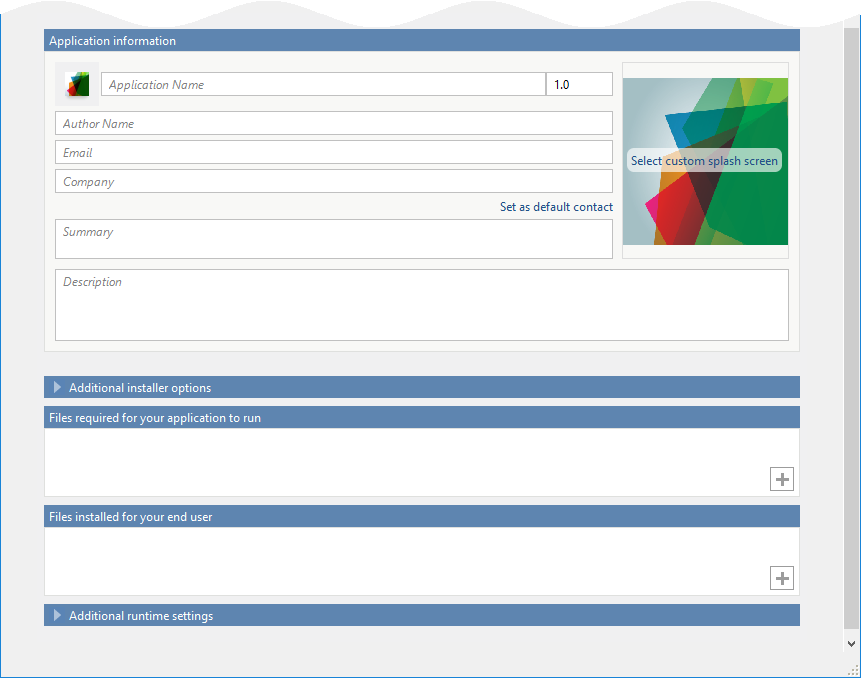

- **Application information** — Editable information about the deployed application. You can also customize the appearance of the standalone application by changing the application icon and splash screen. The generated installer uses this information to populate the installed application metadata.

- **Additional installer options **— Options for editing the default installation path for the generated installer and selecting a custom logo.

- **Files required for your application to run** — Additional files required by the generated application to run. The software includes these files in the generated application installer.

- **Files installed for your end user **— Files that are installed with your application. These files include the generated `readme.txt` file and the generated executable for the target platform. To create a database connection using the standalone application, add the MySQL/C++ Connector file.

- **Additional runtime settings **— Platform-specific options for controlling the generated executable. 

For details about these options, see [Customize the Application](docid:compiler_ug#bt1xwow-1).

To generate the packaged application, click **Package** in the **Package** section on the toolstrip. In the Save Project dialog box, specify the location in which to save the project.

In the **Package** dialog box, verify that the option **Open output folder when process completes** is selected.

When the deployment process is complete, examine the generated output:

- `for_redistribution` — Folder containing the file that installs the application and MATLAB Runtime.

- `for_testing` — Folder containing all the artifacts created by `mcc` (such as binary, JAR, header, and source files for a specific target). Use these files to test the installation. 

- `for_redistribution_files_only` — Folder containing the files required for redistributing the application. Distribute these files to users who have MATLAB or MATLAB Runtime installed on their machines.

- `PackagingLog.txt` — Log file generated by MATLAB Compiler.

## Install and Run Standalone Application

To install the standalone application, double-click the `MyAppInstaller_web` executable in the `for_redistribution` folder.

If you want to connect to the Internet using a proxy server, click **Connection Settings**. Enter the proxy server settings in the provided dialog box. Click **OK**.

To complete the installation, follow the instructions in the installation wizard.

To run your standalone application:

- Open a terminal window.

- Navigate to the folder in which you installed the application.

- Run the application.                                  

## Test Standalone Application on Target Machine

Choose one target machine to test the MATLAB generated standalone application.

Copy the files in the `for_testing` folder to the target machine.

To test your standalone application:

- Open a terminal window.

- Navigate to the `for_testing` folder.

- Run the application. 

## Deploy Standalone Application on Target Machines

Copy the `for_redistribution_files_only` folder to a file location on all target machines where MATLAB or MATLAB Runtime is installed. 

Run the MATLAB generated standalone application on all target machines by using the executable in the `for_redistribution_files_only` folder.

*Copyright 2020 The MathWorks, Inc.*